% Principal Component Analysis of whole brain using Aya's EEG dataset
% across time.
clear;

if exist('H:\', 'dir')  % If H:\ exists, assume this is Computer 1
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';

elseif exist('G:\', 'dir')  % If G:\ exists, assume this is Computer 2
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\BLA';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
% 1- ICA on preprocessed epoched data
% What preprocessing has been done:
% - First prototype the pipeline for BLA (baseline auditory condidtion) for
% the first subject. 
% - Import .set file
file_path = fullfile(input_path,'binepochs filtered ICArej BLAAvgBOS2.set');
EEG = pop_loadset(file_path);

pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Plotting...


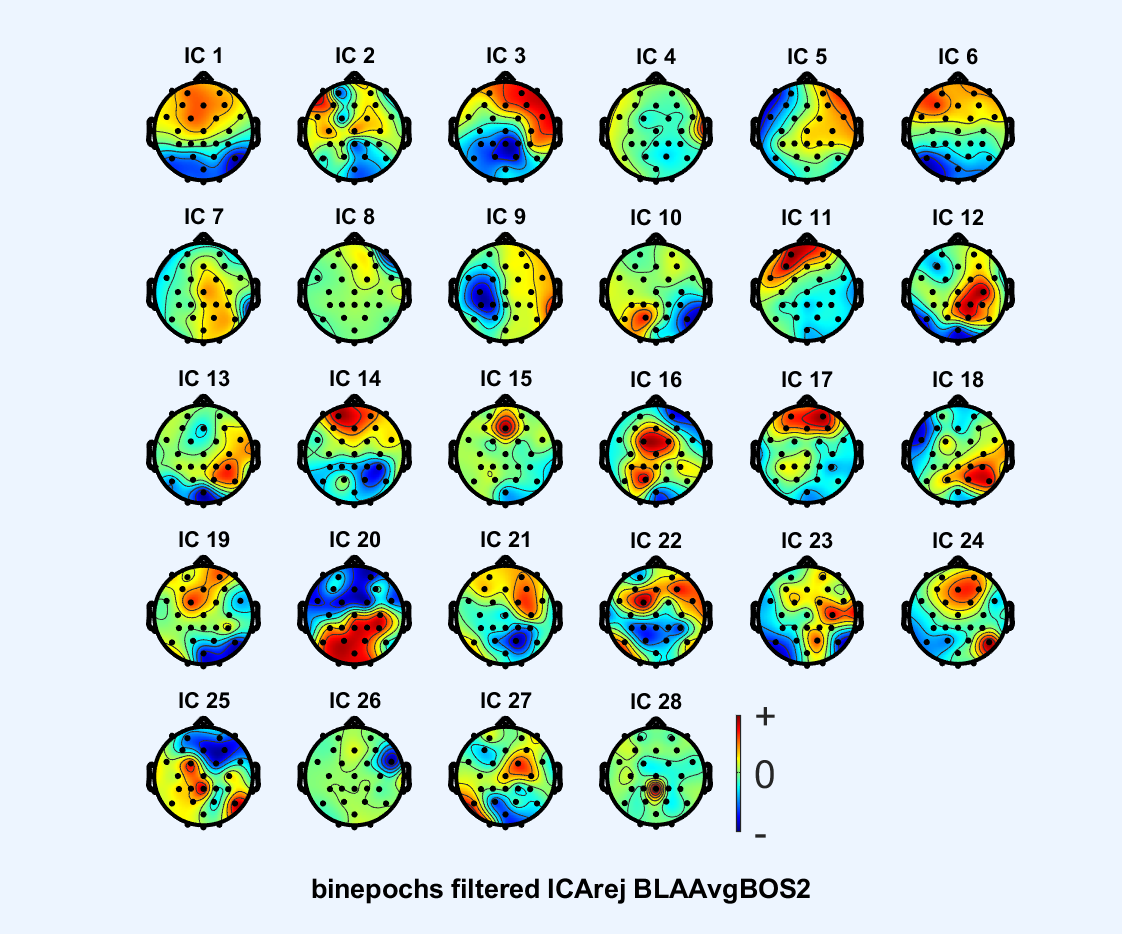

pop_topoplot(EEG, 0, [1:28] ,'binepochs filtered ICArej BLAAvgBOS2',[5 6] ,0,'electrodes','on');

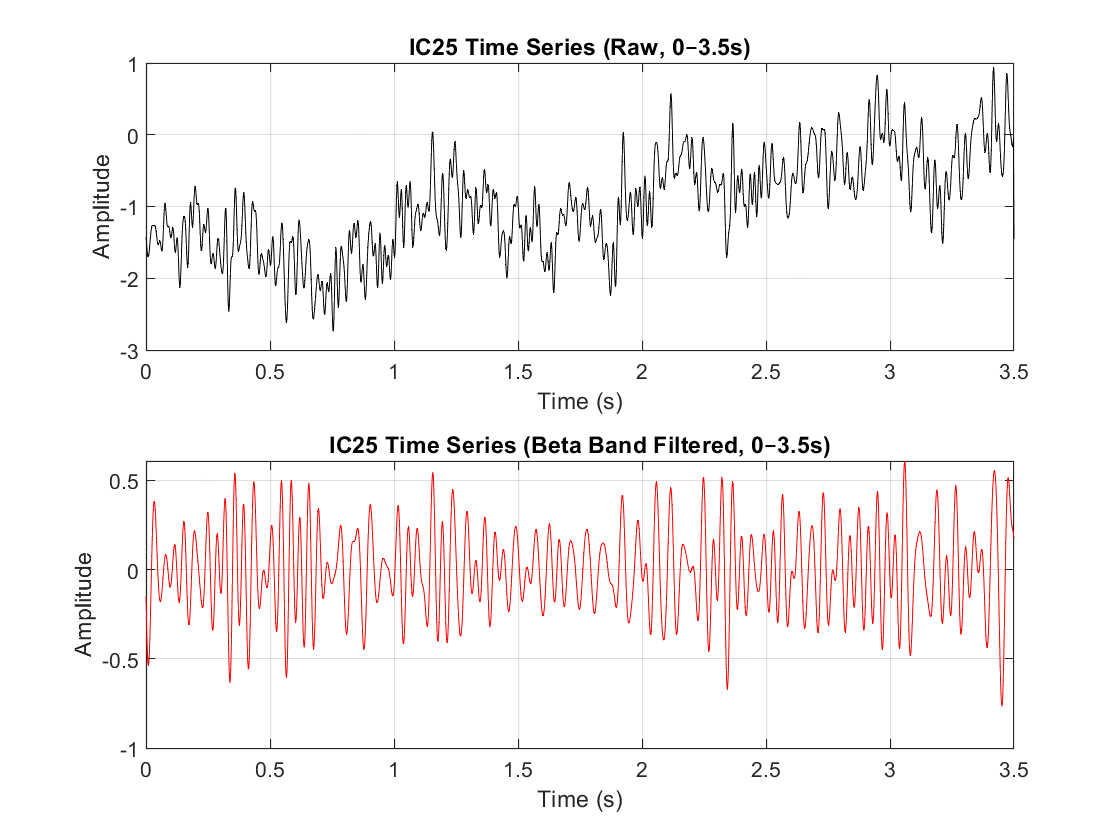


% - First we will do the PCA for just one IC over the somatosensory cortex
% and later loop over all ICs.
% IC25 for BLAAvgBOS2 falls over left central

% - Visualize ICs and chose the IC over left somatosensory cortex
fs = EEG.srate; % Sampling frequency in Hz
ic_data = EEG.icaact(25, :); % IC time series
time_vector = (0:length(ic_data)-1) / fs; % Time in seconds

% - Bandpass filter different EEG bands (theta, alpha, beta, gamma): Here
% we will first focus on beta for its role in attention.
beta_band = [13 30];
% Bandpass filtering:

beta_signal = bandpass(ic_data, beta_band, fs);

% Define time range for plotting (0 to 3.5 seconds)
time_limit = 3.5; % seconds
idx_range = time_vector <= time_limit; % Logical index for the range

% Plot IC time series before and after filtering (limited to 0-3.5s)
figure;
subplot(2,1,1);
plot(time_vector(idx_range), ic_data(idx_range), 'k');
xlabel('Time (s)');
ylabel('Amplitude');
title('IC25 Time Series (Raw, 0–3.5s)');
xlim([0 time_limit]);
grid on;

subplot(2,1,2);
plot(time_vector(idx_range), beta_signal(idx_range), 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('IC25 Time Series (Beta Band Filtered, 0–3.5s)');
xlim([0 time_limit]);
grid on;


% 2- PCA 
% - 2.1 PCA across space: across IC space
% - bin average of 3 trials together (3 epochs): 60 trials/3 = 20 latent
% space images per condition

% For the BLA, BLT and P1, we choose the odd epochs to correspond with auditory onset. 
% Step 1: Extract the odd epochs (epochs 1, 3, 5, ..., 119)
odd_epochs = 1:2:EEG.trials; % Select odd epoch indices

% Step 2: Extract the ICA activations for the selected epochs
% EEG.icaact has dimensions (nICs x nSamples x nEpochs)
ic_data_odd = EEG.icaact(:, :, odd_epochs); % Select odd epochs

% Step 2.2: Bandpass filter beta band (13-30 Hz)
beta_band = [13 30];
beta_signal = zeros(size(ic_data_odd)); % Preallocate
for epoch = 1:size(ic_data_odd, 3)
    beta_signal(:,:,epoch) = bandpass(ic_data_odd(:,:,epoch)', beta_band, fs)';
end


% Step 3: Compute the average IC activations across selected epochs
avg_ic_data = mean(beta_signal, 3); % Average over epochs

% Step 4: Define time windows
num_windows = 20; % Number of time segments
window_size = floor(size(avg_ic_data, 2) / num_windows); % Divide into equal parts:
% each epoch 3.5 sec x512 sample/sec = 1792
% 1792/20 = 89.6, floor(89.6)= 89 samples for window size

% Step 5: Compute PCA for all time windows and find global min/max for color scale
PCA_results = struct(); % Structure to store PCA results
all_scores = cell(1, num_windows); % Store PC scores (variable sizes)
max_PCs = 0; % Track max number of selected PCs across time windows

for w = 1:num_windows
    % Define time window range
    start_idx = (w-1) * window_size + 1;
    end_idx = min(w * window_size, size(avg_ic_data, 2));
    
    % Extract the time-segmented data, 89 time points
    window_data = avg_ic_data(:, start_idx:end_idx);
    
    % Perform PCA
    [coeff, score, latent] = pca(window_data'); 

    % Cumulative variance explained
    explained_variance = cumsum(latent) / sum(latent);
    
    % Find the number of components that explain at least 85% of variance
    num_components = find(explained_variance >= 0.85, 1);
    
    % Ensure at least one component is selected
    if isempty(num_components)
        num_components = 1; 
    end
    
    % Limit to available components (avoid index error)
    num_components = min(num_components, size(score, 2));
    
    disp(['Using ', num2str(num_components), ' PCs']);
    
    % Select the top relevant PCs
    selected_score = score(:, 1:num_components);

    % Store results in struct
    PCA_results(w).time_window = [start_idx, end_idx];
    PCA_results(w).scores = selected_score;
    PCA_results(w).explained_variance = explained_variance(1:num_components);

    % Store scores in a cell array
    all_scores{w} = selected_score;

    % Track the max number of selected PCs
    max_PCs = max(max_PCs, num_components);
end

Using 3 PCs
Using 5 PCs
Using 5 PCs
Using 4 PCs
Using 4 PCs
Using 5 PCs
Using 5 PCs
Using 4 PCs
Using 4 PCs
Using 5 PCs
Using 4 PCs
Using 5 PCs
Using 4 PCs
Using 4 PCs
Using 5 PCs
Using 5 PCs
Using 5 PCs
Using 4 PCs
Using 5 PCs
Using 4 PCs


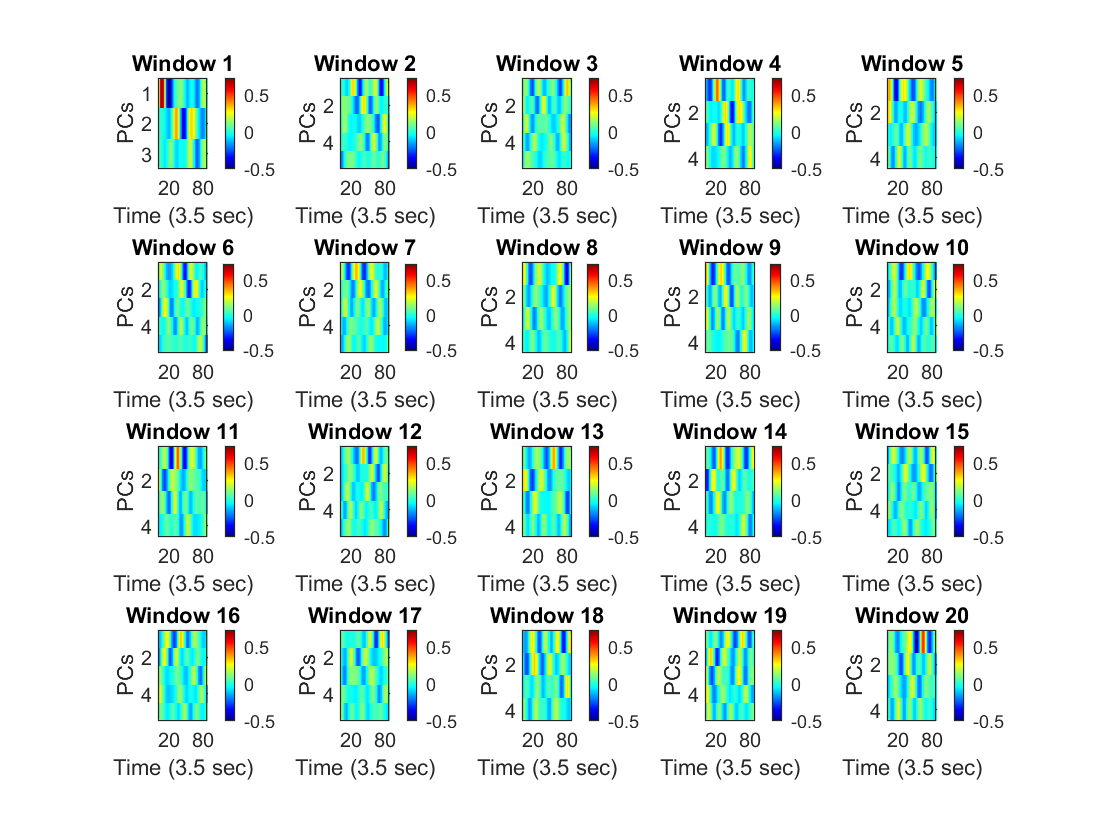


%% Step 6: Normalize all_scores for consistent dimensions
% Ensure all arrays in `all_scores` have the same column count
for w = 1:num_windows
    num_PCs = size(all_scores{w}, 2);
    if num_PCs < max_PCs
        % Pad with NaNs to match max_PCs size
        all_scores{w} = [all_scores{w}, NaN(size(all_scores{w}, 1), max_PCs - num_PCs)];
    end
end

% Convert to matrix after padding
all_scores_matrix = cell2mat(all_scores);

% Get global min/max for consistent color scale
global_min = min(all_scores_matrix(:), [], 'omitnan'); % Ignore NaNs
global_max = max(all_scores_matrix(:), [], 'omitnan');

%% Step 7: Create output directory and save results
condition = 'BLA'; % Change this for different conditions
output_folder = fullfile(output_path, condition);
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

%% Step 8: Plot heatmaps with the same scale
figure;
for w = 1:num_windows
    subplot(4,5,w); % 4 rows x 5 columns = 20 subplots
    imagesc(PCA_results(w).scores'); % Transpose to align dimensions correctly
    colormap jet;
    caxis([global_min global_max]); % Use the same color scale for all plots
    colorbar;
    xlabel('Time (3.5 sec)');
    ylabel('PCs');
    title(['Window ' num2str(w)]);
end

% Extract last token from input filename
[~, file_name, ~] = fileparts(file_path); % Extract filename without extension
last_token = regexp(file_name, '\s+', 'split'); % Split by spaces
last_token = last_token{end}; % Get the last part

% Save the figure with last token in the filename
saveas(gcf, fullfile(output_folder, ['PCA_Heatmaps_' last_token '.png']));

saveas(gcf, fullfile(output_folder, ['PCA_Heatmaps_' last_token '.fig']));

% Save PCA results structure
save(fullfile(output_folder, ['PCA_results_' last_token '.mat']), 'PCA_results');

% - 2.2 PCA across time: Higher temporal resolution latent dynamics with a sliding window of 50
% ms, and 25 ms overlap. 
